## Tutorial 5: Two step optimization part two: the cell refinement module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a published two-photon calcium imaging movie, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information.

M = 'jones.h5:/data';
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.hyperparameter_tuning_flag = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.2;
config.adaptive_kappa = 2;
config.kappa_std_ratio = 1;
output = extractor(M,config);

06-Jul-2024 17:49:48: Signal extraction will run on 1 partitions serially... 
06-Jul-2024 17:49:48: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0761 
	 	 	 	 minimum magnitude: 0.0287 
			 Step #100, found 99 cells... 
			 Step #200, found 173 cells... 
			 Step #300, found 218 cells... 
	 	 	 232 cells found after a total of 351 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 S-step # 1: 232 cells (npx:4, npy:4)
	 	 	 Terminating the cell-refinement for hyperparameter tuning 
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 232 cells.
06-Jul-2024 17:51:30: Total of 232 cells are found.
06-Jul-2024 17:51:30: Removing duplicate cells...
06-Jul-2024 17:51:30: 232 cells were retained after removing duplicates.
06-Jul-2024 17:51:30: All done with EXTRACT! 


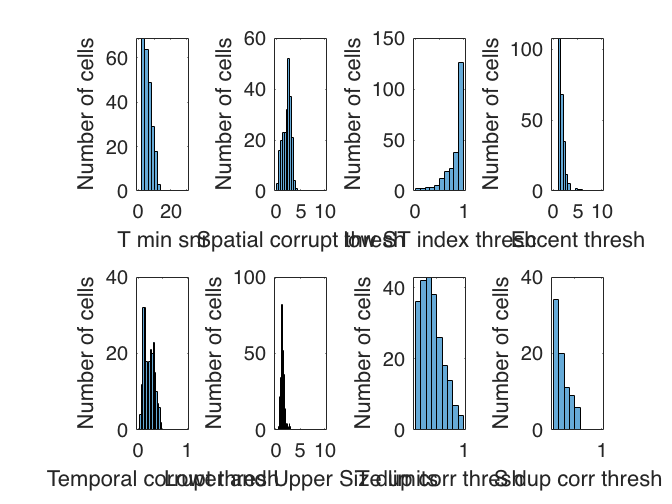

plot_hyperparameter_curves(output)

M = 'jones.h5:/data';
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 10;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.2;
config.thresholds.spatial_corrupt_thresh = 5.5;
config.thresholds.T_dup_corr_thresh = 0.8;
config.adaptive_kappa = 2;
config.kappa_std_ratio = 1;
output = extractor(M,config);
plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])